# Part3: OFDM & Frequency Selective Channel

# Transmitter

N_Bits = 256e0;
Eb = 4;

%Repition Code Enable and Order
RepCode_En = 0;
R = 3;

%Modulation Order (2:BPSK, 4:QPSK, 16:16-QAM)
Modulation_Order = 4;


%Interleaver Setub (8:QPSK case, 16:16-QAM case)
m = 8;

%Number of Subcarriers in the OFDM Symbol
N_SubCarrier = 64;

%Number of Resolvable Paths in the Channel
N_Paths = 1;

%Noise Setup (SNR_dB is the  Noise Raange to Plot aginst)
SNR_dB =linspace(10,10,1);
SNR = 10.^(SNR_dB/10);
SNR = diag(SNR);

BitStream_Data = randi([0 1], [1 N_Bits]);

if RepCode_En == 0
    BitStream = BitStream_Data;
else 
    BitStream = repelem(BitStream_Data,R)
    Eb = Eb/3;
end

## 1) The Bits are Interleaved

%% Interleaver
BitStream = interleaver(BitStream,m);

## 2) Mapping Bits Into QAM Symbol

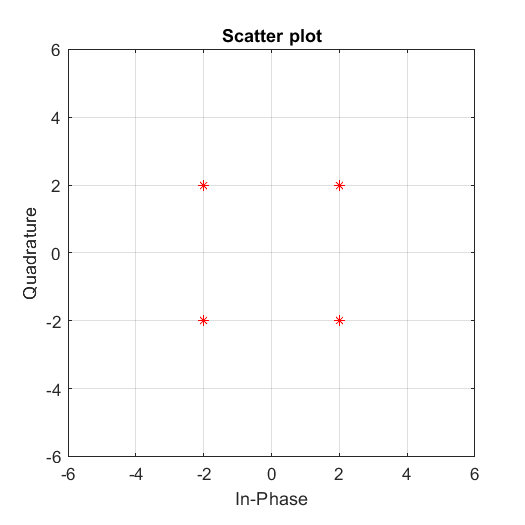

[SymbolStream, Constellation] = Modulate(BitStream,Eb,Modulation_Order);

if RepCode_En == 0
figure
scatterplot(SymbolStream, 1,0,'r*')
grid on
axis([-6 6, -6 6])
end

## 4) Adding the Cyclic Prefix

We will use number of samples in the cyclic prefix to be equal to the number of resorvable paths.

This provides two advatages:

1- This provides the exact guard time to prevent symbols overlap hence avoid ISI

Where each synbol will be extended and overlap with the next symbol after emerging out of the channel but for the cyclic extension.

2- We don't lose subcarriers orthogonality and prevent ICI from occurence

However, practically this extension will provide timing and energy overheads. 

% OFDM_SymbolStream_Ext = CYC_PRE_EXT(OFDM_SymbolStream_time, ...
%     N_SubCarrier, N_Paths-1);
% N_Samples = length(OFDM_SymbolStream_Ext);
% 
% figure
% plot(abs(OFDM_SymbolStream_Ext(1:N_SubCarrier+N_Paths-1)))
% title('Magnitude of One Extended OFDM Symbol vs Time')
% xlabel('n')

#  Channel Model

The Channel is modeled by creating multipaths.

Since the channel is not represented by single paths therefore each symbol will be output of the channel will have extra samples equal to Number of Resolvable Paths -1

By Showing its frequency domain we can note that its indeed frequency selective channel.

U_R = 0;       Sigma_R = sqrt(0.5);
U_I = 0;       Sigma_I = sqrt(0.5);

H = zeros(N_Paths,size(SymbolStream,2));

for i = 1:N_Paths
H_R = randn([1 size(SymbolStream,2)])*Sigma_R + U_R;
H_I = randn([1 size(SymbolStream,2)])*Sigma_I + U_I;

H(i,:) = H_R + H_I*1j;
end

%Noise power will be determined by the SNR value
%SNR = Eb/No
No = Eb*SNR^-1;

N_c = randn([1, size(SymbolStream,2)]);
N_s = randn([1, size(SymbolStream,2)]);
N = N_c + N_s*1j;
N = (No/2)*repmat(N,length(SNR_dB),1);

CHANNEL_OUT = H.*SymbolStream;
CHANNEL_OUT = CHANNEL_OUT + N;

## 3) Creating the OFDM Symbol Stream

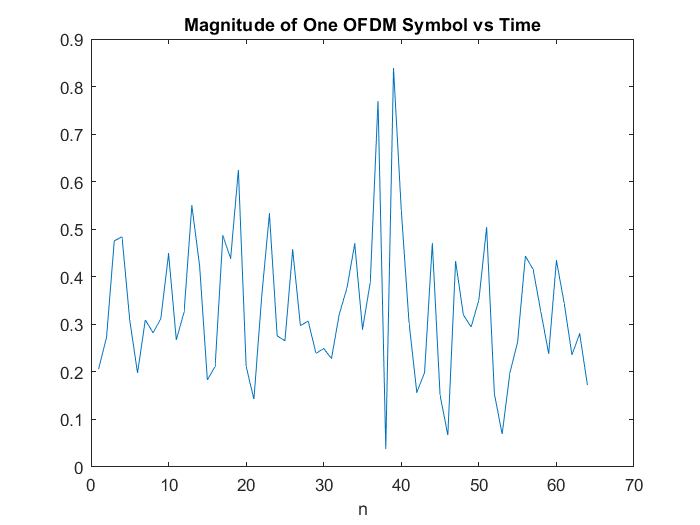

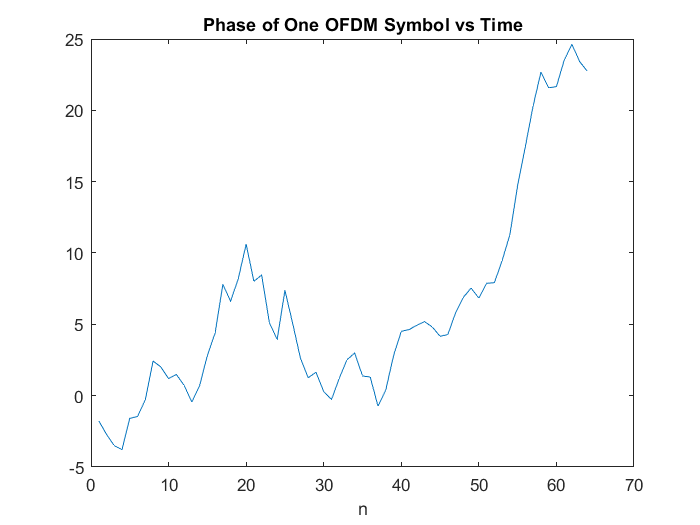

OFDM_SymbolStream_time = IFFT(CHANNEL_OUT,N_SubCarrier);

N_OFDM_Sym = length(OFDM_SymbolStream_time)/N_SubCarrier

N_OFDM_Sym = 8

# Receiver

OFDM_REC_Symbol_Stream = CHANNEL_OUT./H;
Rec_Symbol_Stream = FFT(OFDM_REC_Symbol_Stream,N_SubCarrier)

Rec_Symbol_Stream =    4.7994 + 4.7328i   2.2011 - 1.7097i  -1.0413 - 7.3217i  -2.5471 - 1.1127i  -5.2161 + 3.5077i  -2.3673 - 6.9749i -16.0472 - 1.0784i   2.5839 - 5.3288i   6.2047 - 0.8537i   2.8758 - 8.0962i  -4.5661 -16.7067i   2.9844 + 6.1782i   5.0874 + 0.5268i   3.1830 + 4.8454i  -2.4349 + 1.1659i   4.9158 - 4.2713i  -4.5067 + 4.6407i  -6.1460 - 3.6091i   7.8173 + 0.0654i  -1.1528 -11.3247i   3.9499 + 5.0166i   0.6993 + 2.5662i  -9.1630 - 8.6031i  -7.6184 - 5.0703i   1.0136 + 4.5117i  -7.2626 - 3.8055i   0.4658 - 3.7704i   5.6510 + 0.8245i   7.8163 - 4.2046i  -8.3445 - 4.5638i  -8.7271 + 4.3947i  -5.6307 - 9.7554i   1.2620 + 4.8356i  -0.1199 - 0.8995i   4.4997 +11.6841i   8.4002 + 8.5856i  -8.6343 + 2.6166i   1.5361 + 2.9473i   4.5497 - 3.9103i   9.0918 - 9.0399i   7.2946 + 0.1627i  -4.6216 + 0.9699i  -0.7618 + 7.9095i   0.4088 - 1.9521i  -0.0803 - 9.4332i   6.2354 - 0.4588i   6.8859 + 0.0639i   0.4547 -14.5108i   3.1117 - 8.0120i  -2.1769 + 3.4341i


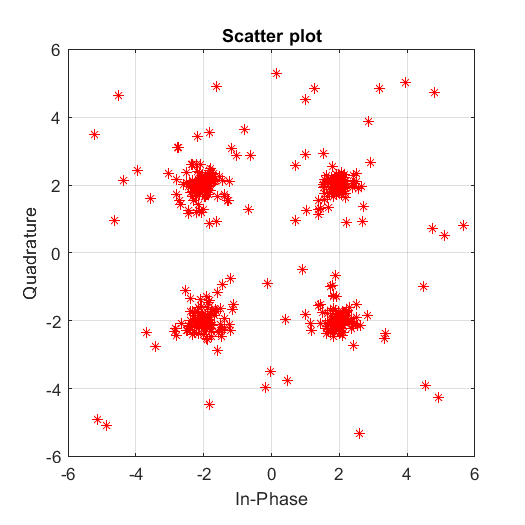

figure
scatterplot(Rec_Symbol_Stream, 1,0,'r*')
grid on
axis([-6 6, -6 6])

function [SymbolStream, S] = Modulate(BitStream, Eb, Order)
%This function takes the bit stream and modulate it according
%to modulation order
%Modulation order varies from 2:BPSK 4:QPSK 16:16-QAM
%Eb: Energy per Bit

N_Bits = length(BitStream);

switch (Order)
    case 2
        A = sqrt(Eb);
        SymbolStream = (2*BitStream-1)*A;
        S = 2;
    
    case 4
        A = sqrt(Eb);
        %Creating the constellation:
        %Index represents the mapped bits - 1
        %ex: 00-> index:1 -> (-1-j)*A
        S(1) = - 1 - 1j;
        S(2) = - 1 + 1j;
        S(3) =   1 - 1j;
        S(4) =   1 + 1j;
        S = S*A;
        
        SymbolStream = reshape(BitStream,[2, N_Bits/2])';
        SymbolStream = num2str(SymbolStream);
        SymbolStream = bin2dec(SymbolStream)';
        SymbolStream = S(SymbolStream+1);
        
    case 16
        % Eb = 2.5E -> A = sqrt(E)
        A = sqrt(0.4*Eb);
        %Creating the constellation:
        %Index represents the mapped bits - 1
        %ex: 0000-> index:1 -> (-3-3j)*A
        S(1) = - 3 - 3j;
        S(2) = - 3 - 1j;
        S(3) = - 3 + 3j;
        S(4) = - 3 + 1j;
        S(5) = - 1 - 3j;
        S(6) = - 1 - 1j;
        S(7) = - 1 + 3j;
        S(8) = - 1 + 1j;
        S(9) =   3 - 3j;
       S(10) =   3 - 1j;
       S(11) =   3 + 3j;
       S(12) =   3 + 1j;
       S(13) =   1 - 3j;
       S(14) =   1 - 1j;
       S(15) =   1 + 3j;
       S(16) =   1 + 1j;
        S = S*A;
        
        SymbolStream = reshape(BitStream,[4, N_Bits/4])';
        SymbolStream = num2str(SymbolStream);
        SymbolStream = bin2dec(SymbolStream)';
        SymbolStream = S(SymbolStream+1);
        
        
        
    
end

end

function [Out_BitStream] = Decode(SymbolStream, S, RepCode_En)
%This function takes the Symbol Stream after channel inversion
%And Decodes it according maximum Liklihood decoding
%aka: minimum distance to contellation point,
%since we are using eqiprobable signals
%Decoded symbols are directly converted to bits
%S is an array that carries the constellation points
%The Function then applies  Hard Decision Decoding
%Where its index is the equivalent binary value + 1

N_Symbols = length(SymbolStream);
Order = length(S);

if(S == 2)
    %BPSK case
    SymbolStream = real(SymbolStream);
    Out_BitStream(SymbolStream>0) = 1;
    Out_BitStream(SymbolStream<0) = 0;
else
    SS_mod = repmat(SymbolStream,Order,1);
    Rep_con = transpose(repmat(S,N_Symbols,1));
    Distance = SS_mod - Rep_con;
    Distance = abs(Distance);
    
    [~, Index] = min(Distance);
    %Output Bit stream in decimal
    Out_BitStream = Index-1;
    Out_BitStream = decimalToBinaryVector(Out_BitStream,log2(Order),'MSBFirst')';
    Out_BitStream = reshape(Out_BitStream,1,N_Symbols*log2(Order));
end
%decoding the repetition-3 code if used 
if(RepCode_En == 1)
        Out_BitStream = reshape(Out_BitStream,3,[]);
        Out_BitStream = mode(Out_BitStream);
end 
end

function [TimeDomainSignal] = IFFT(SymbolStream, N_Points)
%N_Points: is the #Subcarriers int the OFDM Symbol

N_QAM_SYM = length(SymbolStream);
N_OFDM_SYM = N_QAM_SYM/N_Points;

TimeDomainSignal = transpose(reshape(SymbolStream, [N_Points, N_OFDM_SYM]));

for i = 1:N_OFDM_SYM
    TimeDomainSignal(i,:) = ifft(TimeDomainSignal(i,:));
end
figure
plot(abs(TimeDomainSignal(1,:)))
title('Magnitude of One OFDM Symbol vs Time')
xlabel('n')
figure
plot(phase(TimeDomainSignal(1,:)))
title('Phase of One OFDM Symbol vs Time')
xlabel('n')

TimeDomainSignal = reshape(TimeDomainSignal', [1, N_Points*N_OFDM_SYM]);
end

function [Freq_Dom_Sig] = FFT(OFDM_Stream, N_Points)
%N_Points: is the #Subcarriers int the OFDM Symbol

N_OFDM_Symbols = length(OFDM_Stream)/N_Points;

Freq_Dom_Sig = transpose(reshape(OFDM_Stream, [N_OFDM_Symbols, N_Points]));

for i = 1:N_OFDM_Symbols
    Freq_Dom_Sig(i,:) = fft(Freq_Dom_Sig(i,:));
end

Freq_Dom_Sig = reshape(Freq_Dom_Sig', [1, N_Points*N_OFDM_Symbols]);
end

function [Pre_Ext_SYM] = CYC_PRE_EXT(Symbol_Array, N_SubCarrier, Ext_Size)
%SymbolSize is represented by the Size of the symbol from IFFT
%aka: it's the #subcarriers per symbol
%Ext_Size: is the #samples to be cyclically extended

N_Symbols = length(Symbol_Array)/N_SubCarrier;

Pre_Ext_SYM = transpose(reshape(Symbol_Array,[N_SubCarrier, N_Symbols]));

Ext_Sym = Pre_Ext_SYM(:,N_SubCarrier-Ext_Size+1:N_SubCarrier);
if Ext_Size == 1
    Ext_Sym = Ext_Sym(:,1);
end

Pre_Ext_SYM = [Ext_Sym, Pre_Ext_SYM];

[X, Y] = size(Pre_Ext_SYM);
Pre_Ext_SYM = reshape(transpose(Pre_Ext_SYM), [1, X*Y]);
end

function [EXT_REM] = REM_PRE_EXT(Symbol_Array, N_SubCarrier, Ext_Size)
%SymbolSize is represented by the Size of the symbol from IFFT
%aka: it's the #subcarriers per symbol
%Ext_Size: is the #samples to be cyclically extended

Ext_Sym_Size = N_SubCarrier + Ext_Size;
N_Symbols = length(Symbol_Array)/Ext_Sym_Size;

EXT_REM = transpose(reshape(Symbol_Array, [Ext_Sym_Size, N_Symbols]));
EXT_REM = EXT_REM(:,Ext_Size+1:end);

EXT_REM = reshape(transpose(EXT_REM), [1, N_Symbols*N_SubCarrier]);
end
function data_out = interleaver(data,m)
L = 16; % Number of rows(m) and columns(L)
nb = m*L;  % Size of interleaver
k = 0:nb-1;  % interleaver output indexing vector
i = L*mod(k,m)+floor(k/m);  % intermediate variable
j = (nb/2)*floor(2*i/nb)+mod((i+nb),nb/2); % interleaver input indexing vector
data_out = zeros(1,length(data));
for ii = 1: length(data)/(m*L)
    temp = data((ii-1)*nb+1:ii*nb);
    data_out((ii-1)*nb+1:ii*nb) = temp(j+1);
end
end

function data_out = deinterleaver(data,m)
L = 16; % Number of rows(m) and columns(L)
nb = m*L;  % Size of interleaver
k = 0:nb-1;  % interleaver output indexing vector
i = L*mod(k,m)+floor(k/m);  % intermediate variable
j = (nb/2)*floor(2*i/nb)+mod((i+nb),nb/2); % interleaver input indexing vector
data_out = zeros(1,length(data));
temp = zeros(1,nb);
for ii = 1: length(data)/(m*L)
    temp(j+1) = data((ii-1)*nb+1:ii*nb);
    data_out((ii-1)*nb+1:ii*nb) = temp;
end

end

function [Channel_Out] = CONV(OFDM_Symbol_Stream,Ch)
    Channel_Out = OFDM_Symbol_Stream .* Ch;
    Channel_Out = [Channel_Out;zeros(size(Ch,2)-1,size(Ch,2))];
    
    for i = 2:size(Ch,2)
       Channel_Out(:, i) = circshift(Channel_Out(:, i), i-1);
    end
    Channel_Out = transpose(sum(Channel_Out, 2));
end